# Getting Started with Hybrid Equations Toolbox

## Description

To get started, a webinar introducing the HyEQ Toolbox is available [here](http://www.mathworks.com/videos/hyeq-a-toolbox-for-simulation-of-hybrid-dynamical-systems-81992.html) (a free registration is required).

A hybrid system is a dynamical system with continuous and discrete dynamics. Several mathematical models for hybrid systems have appeared in literature. In this paper, we consider the framework for hybrid systems used in~\cite{SCN13,GST09,ST10,San11}, where a hybrid system $\mathcal H$ on a state space $\mathbb{R}^n$ with input space $\mathbb{R}^m$ is defined by the following objects:

- A set $C \subset \mathbb{R}^n \times \mathbb{R}^m$ called the *flow set*.

- A function $f : \mathbb{R}^n \times\mathbb{R}^m \to \mathbb{R}^n$ called the *flow map*.

- A set $D \subset \mathbb{R}^n \times \mathbb{R}^m$ called the *jump set*.

- A function $g : \mathbb{R}^n \times \mathbb{R}^m \to \mathbb{R}^n$ called the *jump map.*

We consider the simulation in MATLAB/Simulink of hybrid systems $\mathcal  H = (C,f,D,g)$ written as


$$\mathcal H: \begin{cases}\dot x = f(x, u) & x \in C \\ x^+ = g(x) & x \in 
D \end{cases}$$


where $x \in \mathbb{R}^n, u \in \mathbb{R}^{m}$.

The flow map $f$ defines the continuous dynamics on the flow set $C$, while the jump map $g$ defines the discrete dynamics on the jump set $D$. These objects are referred to as the *data* of the hybrid system $\mathcal H$, which at times is explicitly denoted as $\mathcal H = (C,f,D,g)$. We illustrate this framework in a simple, yet rich in behavior, hybrid system.

## Features

<Provide an overview of the features that your toolbox integrates with MATLAB here.>

## Examples

### **Bouncing Ball System**

In this example, we demonstrate a new approach to solving a hybrid system and plotting a solution. In `BouncingBallHybridSystem.m`, we define a hybrid system by creating a subclass of the `HybridSystem `class and implementing the `flow_map, jump_map, flow_set_indicator, jump_set_indicator` functions in order to specify $f, g, C$, and $D
$, respectively.

We can then create an instance of the bouncing ball system:

system_bb = BouncingBallHybridSystem();

A solution is then computed by calling the `solve` function on `system_bb` with the initial state and time spans as arguments. The `solve` function returns a `HybridSolution` object that contains information about the solution (see, in particular, the `t, j,` and `x` properties to recover the standard output from `HyEQSolver`). 

x0 = [1;0];
tspan = [0, 20];
jspan = [0, 30];
sol_bb = system_bb.solve(x0, tspan, jspan)

sol_bb =   HybridSolution with properties:

                    t: [737×1 double]
                    j: [737×1 double]
                    x: [737×2 double]
               f_vals: [737×2 double]
               g_vals: [737×2 double]
               C_vals: [737×1 uint8]
               D_vals: [737×1 uint8]
                   x0: [1 0]
           jump_times: [30×1 double]
          dwell_times: [30×1 double]
        flow_duration: 8.2003
       min_dwell_time: 0.0426
           jump_count: 30
    termination_cause: J_REACHED_END_OF_JSPAN


#### Plot flows

The `HybridPlotBuilder` class is used to plot solutions and provides options for configuring the color, line styles, markers, and plot orders. To generate plots, we create a `HybridPlotBuilder` object then configure the plot via a series of function calls. For the bouncing ball example, our state contains two components, so we set two titles and two labels. When then pass the solution object to the `plot_builder_bb.plotflows` function.

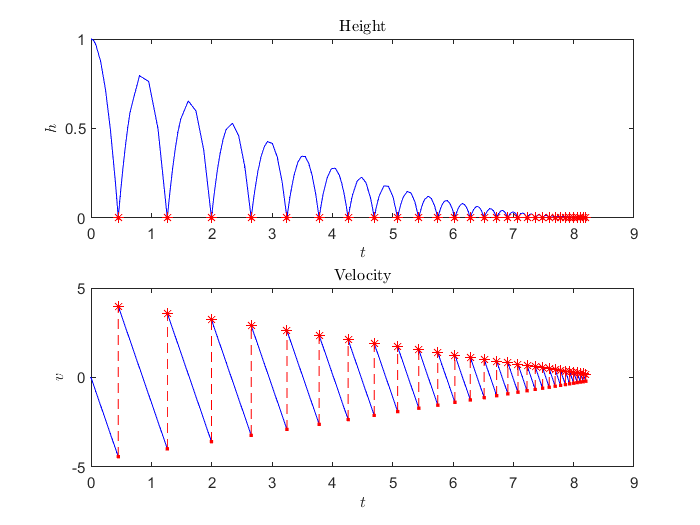

figure()
plot_builder_bb = HybridPlotBuilder();
plot_builder_bb.title("Height", "Velocity") ...
    .labels('$h$', '$v$') ...
    .plotflows(sol_bb);

 Note that in this example we chain together function calls on `plot_builder_bb but could rewrite it more verbosely as `

plot_builder_bb.title("Height", "Velocity");
plot_builder_bb.labels('$h$', '$v$');
% etc.

#### Plot Hybrid Arcs

In this example, we switch the order of the plots by calling `slice([2, 1])`, which causes component 2 to be plotted first, followed by component 1 (the `slice` function can be also be used to reduce the dimension of system by specifying only some components). The final call to `plotHyrbidArc` generates plots of the solution versus both `t` and `j.`

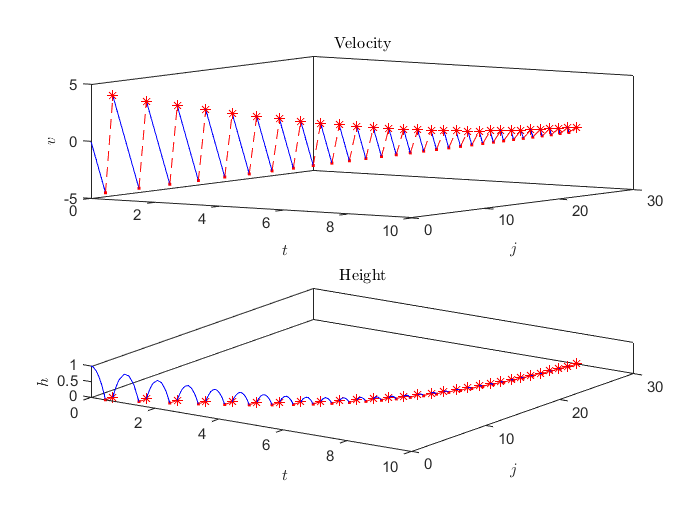

figure()
plot_builder_bb.title("Height", "Velocity") ... % The order of the titles must match the order of the components in the solution.
    .slice([2, 1]) ... % Switch the order
    .plotHyrbidArc(sol_bb);

The axes are linked so rotation, zooming, etc. in one subplot is mirrored in all the others plot (the one exception is vertical scaling, which is left independent for each component).

#### Plot state

We can also plot the trajectory of the system in phase space as follows. When plotting in phase space, only one title is used.

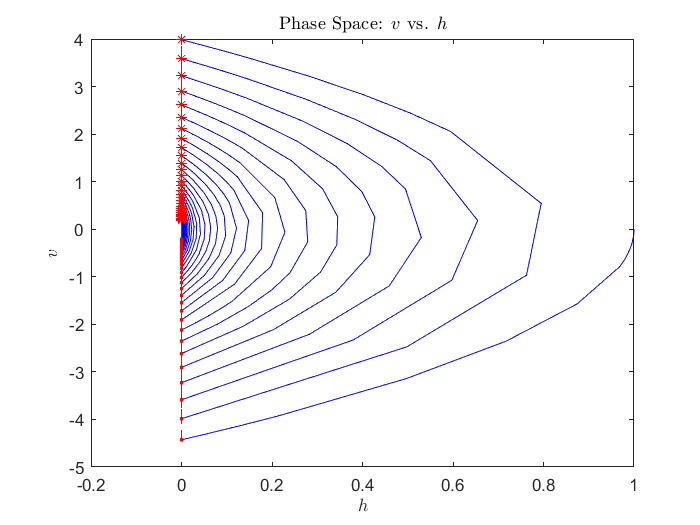

figure()
plot_builder_bb = HybridPlotBuilder();
plot_builder_bb.title("Phase Space: $v$ vs. $h$") ...
    .labels('$h$', '$v$') ...
    .plot(sol_bb)

Next, we plot the trajectory of the system in phase space using a customized plotting configuration. Note that we are using the same object 'plot_builder_bb,' so the values we set for the title and labels are preserved.

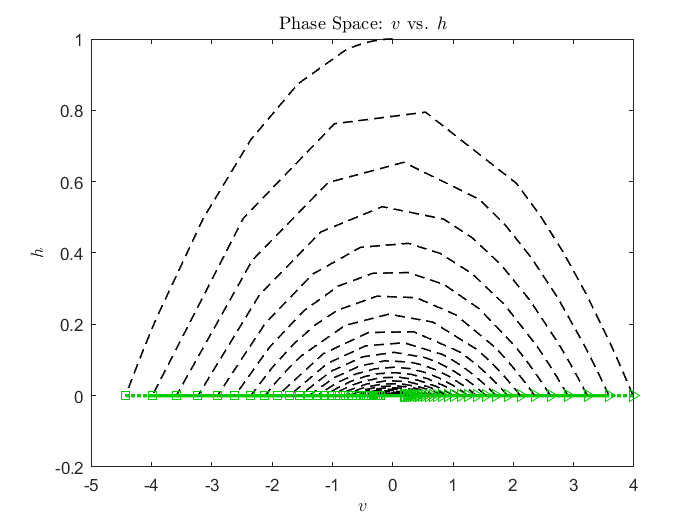

figure()
plot_builder_bb ...
    .flowColor("black") ...
    .flowLineStyle("--") ...
    .flowLineWidth(1) ...
    .jumpColor([0, 0.8, 0]) ... % RGB for jump color
    .jumpStartMarker("s") ... % square marker
    .jumpEndMarker(">") ... % triangle
    .jumpLineWidth(2) ...
    .jumpLineStyle(":") ...
    .jumpStartMarkerSize(6) ...
    .jumpEndMarkerSize(6) ...
    .slice([2, 1]) ... % Switch the order of the variables.
    .plot(sol_bb)

## Plot dwell times

The `HybridUtils.plotDwellTimes` function plots the dwell time for each interval of flow for a given solution object. 

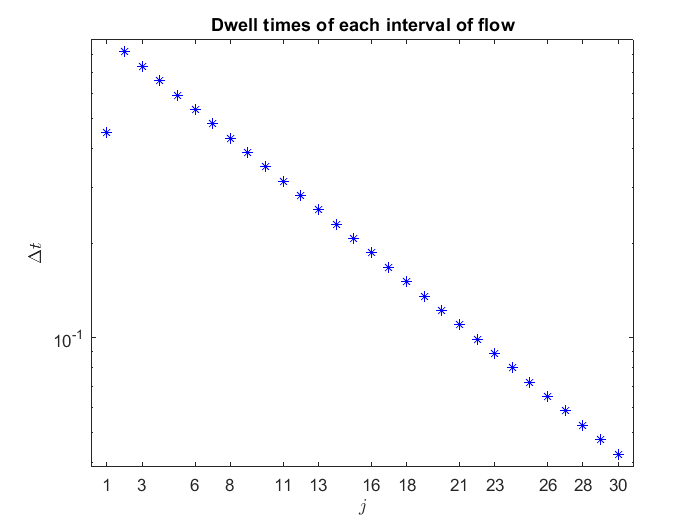

figure()
HybridUtils.plotDwellTimes(sol_bb)

### Plot state for a 3D system

The following example shows a 3-dimensional hybrid system (based on Example 6.20 from the *Hybrid Dynamical Systems* textbook with continuous time $t$ as the third component).

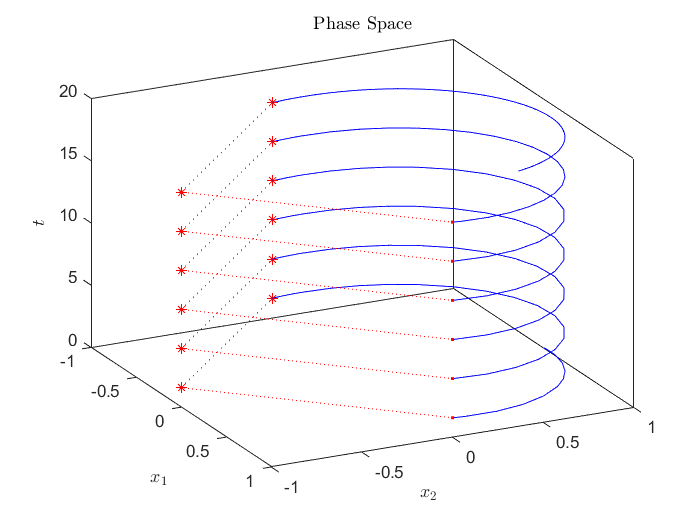

figure(6)
clf
system_3D = Example3DHybridSystem();
x0 = [0; 1; 0];
tspan = [0, 20];
jspan = [0, 100];
sol_3D = system_3D.solve(x0, tspan, jspan);

HybridPlotBuilder().title("Phase Space") ...
    .labels("$x_1$", "$x_2$", "$t$") ...
    .jumpLineStyle(":") ...
    .plot(sol_3D)
view([63.6 28.2])

### Plotting System Modes

This example demonstrates the ability to change the appearance of portions of a hybrid plot. The system `system_with_modes` consists of a continuous-valued variable $z \in \mathbb{R}^2
$ and a discrete-valued variable $q \in \{0, 1\}$. 

We use `slice([1, 2]) `to omit the $q$ variable from the plot. Then, we create an array `q` that contains the value of $q$ at each time step. Calling `filter(q == 0)` then allows us to plot only the time steps where $q(t, j) = 0$

figure(7);
% A 3D system with a continuous variable z \in \reals^2
% and a discrete variable q \in {0, 1}
system_with_modes = ExampleModesHybridSystem();

for i=1:7
    % Create a random initial condition and solve.
    z0 = 20*rand(2, 1) - 10;
    q0 = round(rand());
    sol_modes = system_with_modes.solve([z0; q0], [0, 10], [0, 10], "silent");
    
    q = sol_modes.x(:, 3);
    
    % Plot the [1, 2] components (that is, the first two components) of
    % sol_modes at all time steps where q == 0. 
    builder = HybridPlotBuilder();
    builder.title("Phase Portrait") ...
        .labels("$x_1$", "$x_2$") ...
        .slice([1,2]) ... % Pick which state components to plot
        .filter(q == 0) ... % Only plot points where q is 0.
        .plot(sol_modes)
    hold on
    % Plot in black the solution (still only the [1,2] components) for all time
    % steps where q == 1. 
    builder.flowColor("black") ...
        .jumpColor("none") ...
        .filter(q == 1) ... % Only plot points where q is 1.
        .plot(sol_modes)
end

Next, we add a legend. Note that in the loop above, a new instance of `HybridPlotBuilder` is created in each iteration, so the legend will only have two entries. 

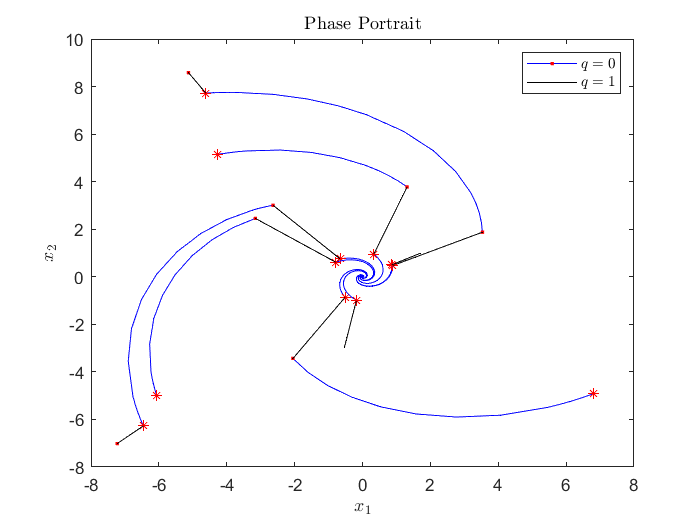

builder.legend("$q = 0$", "$q = 1$");

## Quick System Definition with *HybridSystemBuilder*

We also provide a quicker way to create a hybrid system in-line instead of creating a new subclass of `HybridSystem`. (This method is not reccomended for long-term use or complex systems.)

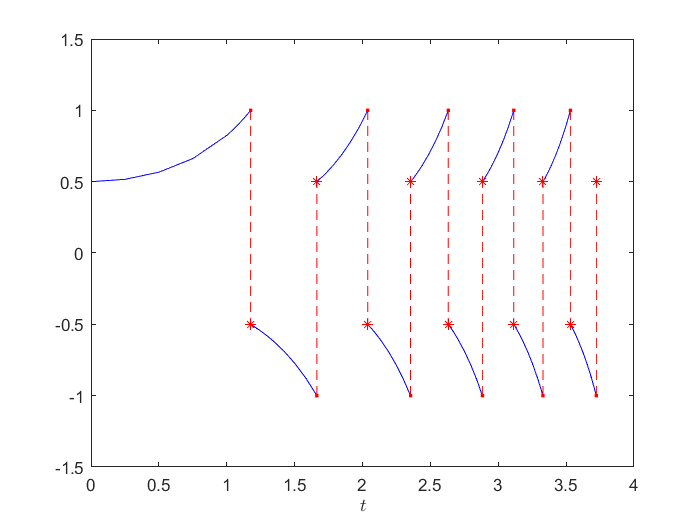

figure()
system_EZ = HybridSystemBuilder() ...
            .f(@(x, t) t*x) ... % the function arguments can by (x), (x,t), or (x, t, j).
            .g(@(x) -x/2) ...
            .C(@(x) abs(x) <= 1) ...
            .D(@(x) 1) ...
            .flowPriority() ... % Select flow priority.
            .build();
sol_EZ = system_EZ.solve(0.5, [0, 10], [0, 10]);
plot(sol_EZ) % Note that we can call "plot" on HybridSolutions. This creates a default HybridPlotBuilder to generate the plot.